cfgVHT = wlanVHTConfig;

cfgVHT.ChannelBandwidth = 'CBW20';
cfgVHT.MCS = 8 ;
txWaveform = wlanWaveformGenerator([1;0;0;1],cfgVHT,...
    'WindowTransitionTime',0);

tgn = wlanTGnChannel('LargeScaleFadingEffect','None');
% tgn = wlanTGnChannel('DelayProfile','Model-D');
zz = 100;
txWaveform = [zeros(zz,1);txWaveform];

snr = 20;
fadedSig = tgn(txWaveform);
% rxWaveform =fadedSig;
rxWaveform = awgn(fadedSig,snr,0);

% ini_offset = 1;

% Self-generated STF




result_auto = zeros(160+zz,1);

% Self-generated STF
% rxWaveform = zeros(1000,1);
% rxWaveform(101:260) = STFifft_full;

for aa = 1:160+zz
        
        result_auto(aa) =  abs(rxWaveform(aa+16:aa+16+15)'* rxWaveform(aa:aa+15)) ;
        result_auto(aa) = result_auto(aa)^2/(abs((rxWaveform(aa+16:aa+16+15)'*rxWaveform(aa+16:aa+16+15))))^2;
                
end
% [a, b] = max(result_auto);
% b
k = find(result_auto>0.3,5)

k =    102
   103
   104
   105
   106


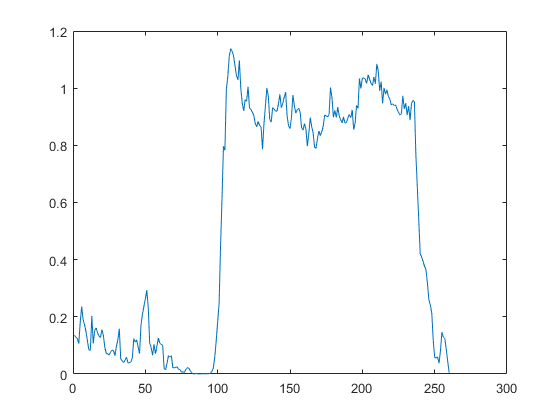

plot(result_auto)